%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( t2500f10, lns2500f10 );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
%creating errorbars
grid on
hold on
a=s2500f10

a =    13.7800
   16.6300
   21.1000
   29.1500
   48.0000


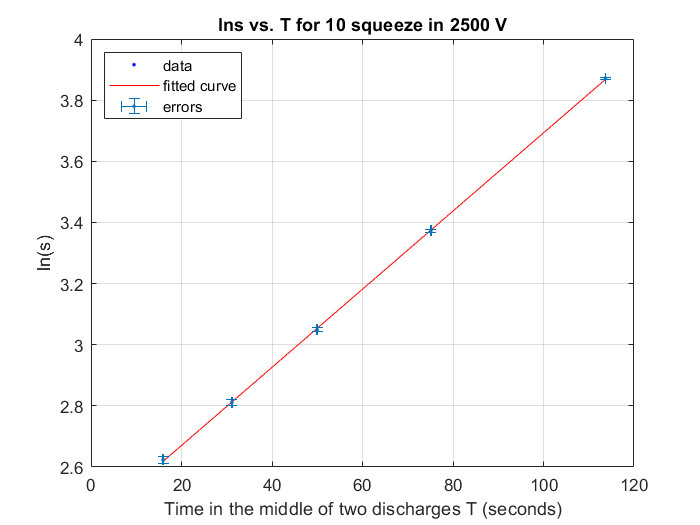

bincenters= t2500f10;
yneg=[0.14/13.78 0.14/16.63 0.14/21.10 0.14/29.15 0.14/48.00];
ypos=yneg;
xpos=[0.071 0.071 0.071 0.071 0.071];
xneg=xpos;
errorbar(bincenters,lns2500f10,yneg,ypos,xpos,xneg,'.');

%legends
xlim('auto')
ylim('auto')
legend({'data','fitted curve','errors'},'Location','northwest')
xlabel('Time in the middle of two discharges T (seconds)')
ylabel('ln(s)')
title('lns vs. T for 10 squeeze in 2500 V')

%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds) meaning 2 sisgma distance:
 %      p1 =     0.01278  (0.01259, 0.01297)
  %     p2 =       2.415  (2.402, 2.427)

%Goodness of fit:
 % SSE: 6.313e-05
  %R-square: 0.9999
  %Adjusted R-square: 0.9999
  %RMSE: 0.004587
  
  